% load image
img_names =    ["SpecifyLineWidthMarkerSizeAndMarkerColorExample_01.jpg"
                "plotting_01.jpg"
                "ScatterTableExample_01.jpg"
                "SpecifyLineWidthMarkerSizeAndMarkerColorExample_01.jpg"
                "Test.png"
                "VaryCircleSizeandColorExample_01.jpg"
               ]

img_names = 6×1 string array
    "SpecifyLineWidthMarkerSizeAndMarkerColorExample_01.jpg"
    "plotting_01.jpg"
    "ScatterTableExample_01.jpg"
    "SpecifyLineWidthMarkerSizeAndMarkerColorExample_01.jpg"
    "Test.png"
    "VaryCircleSizeandColorExample_01.jpg"



img_name = img_names(5)

img_name = "Test.png"

[img,~] = imread(img_name)

img = 655×875×3 uint8 array
img(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   2

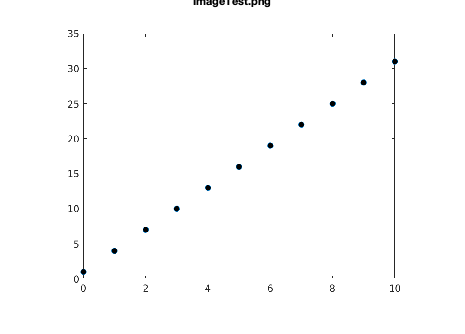

imshow(img, [])
title('Image' + img_name)

img = img(:,:,1)

img = 655×875 uint8 matrix
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   2


% size of image
[img_rows, img_cols] = size(img)

img_rows = 655

img_cols = 875


% size of coordinate area
title_name = 'Mark X-Axis';
message = 'Mark minimum and maximum of the X-Axis';
uiwait(msgbox(message, title_name))
x_axis_img = ceil(readPoints(img_name, 2))'

x_axis_img =    116   582
   792   582


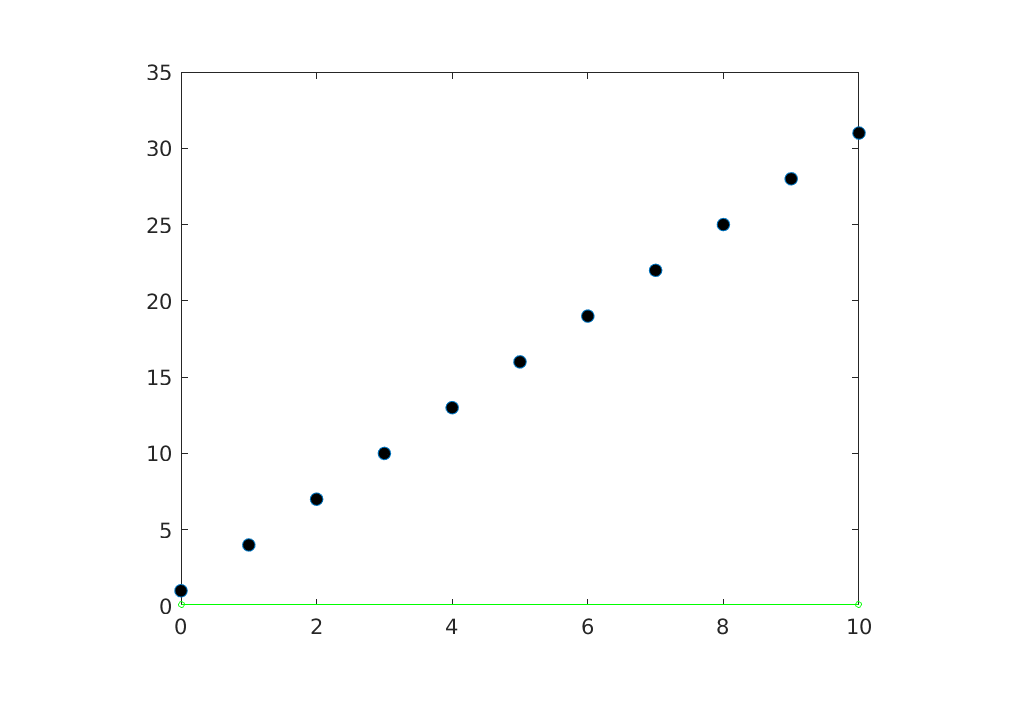


title_name = 'Mark Y-Axis';
message = 'Mark minimum and maximum of the Y-Axis';
uiwait(msgbox(message, title_name))

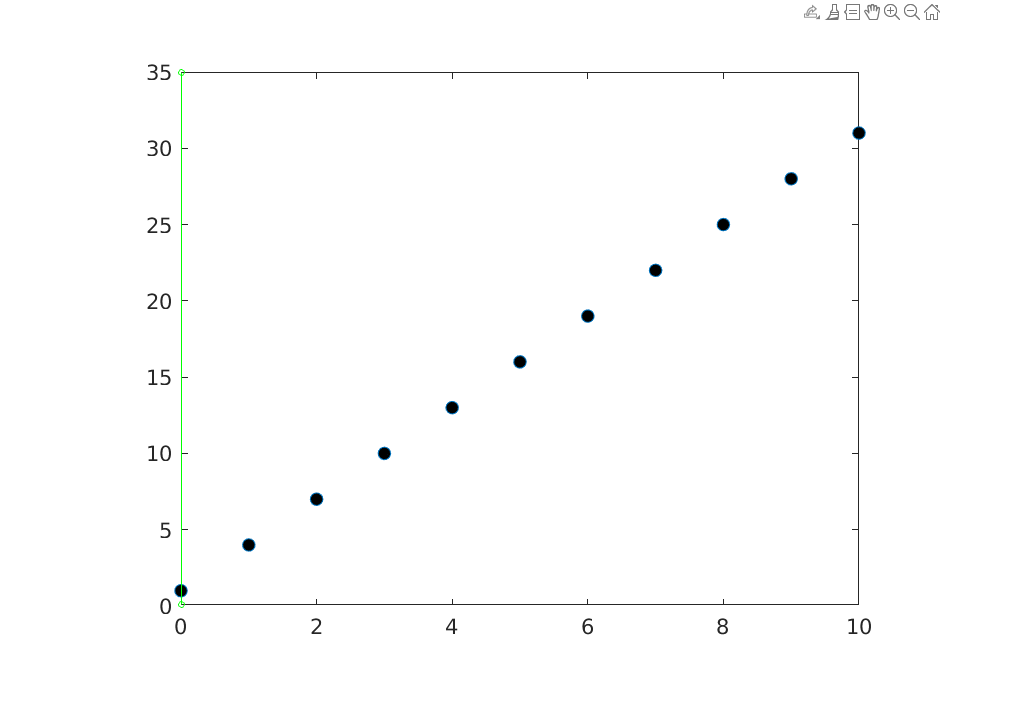

y_axis_img =    116   582
   116    50


y_axis_img = ceil(readPoints(img_name, 2))'

% actual axis values
axes_input = inputdlg({'x1','x2','y1', 'y2'},...
    'Enter x and y axis limits',...
    [1 100; 1 100; 1 100 ; 1 100]);

axes_input = cell2mat(cellfun(@str2num,axes_input,'un',0));
x_axis = [axes_input(1:2)]'

x_axis =      0    10


y_axis = [axes_input(3:4)]'

y_axis =      0    35


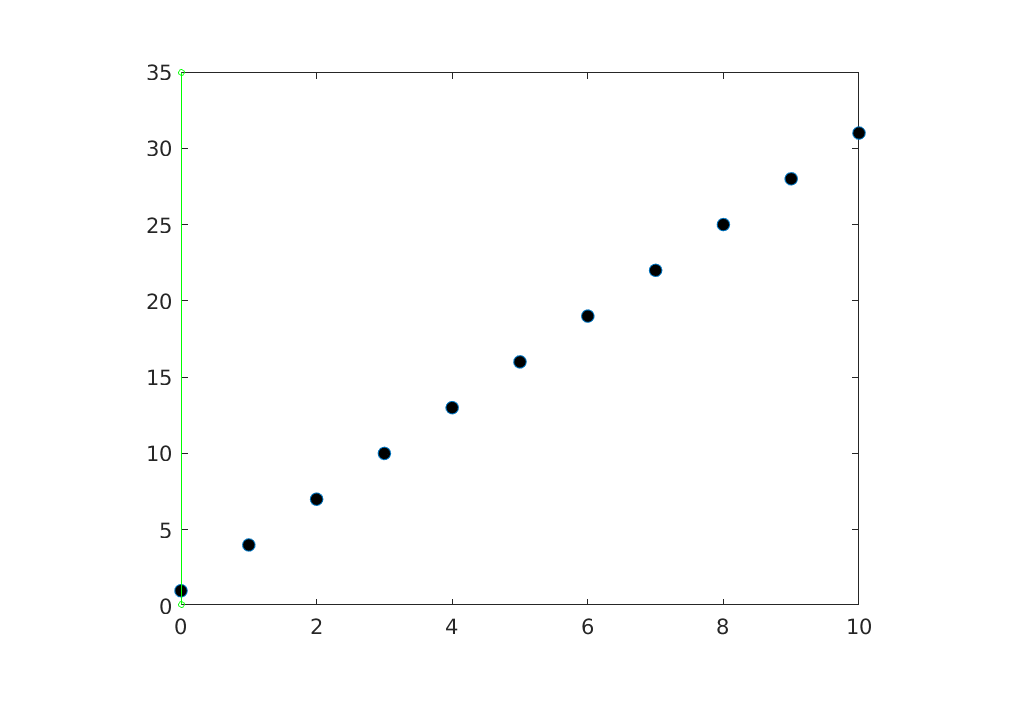

% Mark shape of data point
message = 'Mark two clicks around the data point shape';
title_name = 'Mark shape';
uiwait(msgbox(message, title_name))

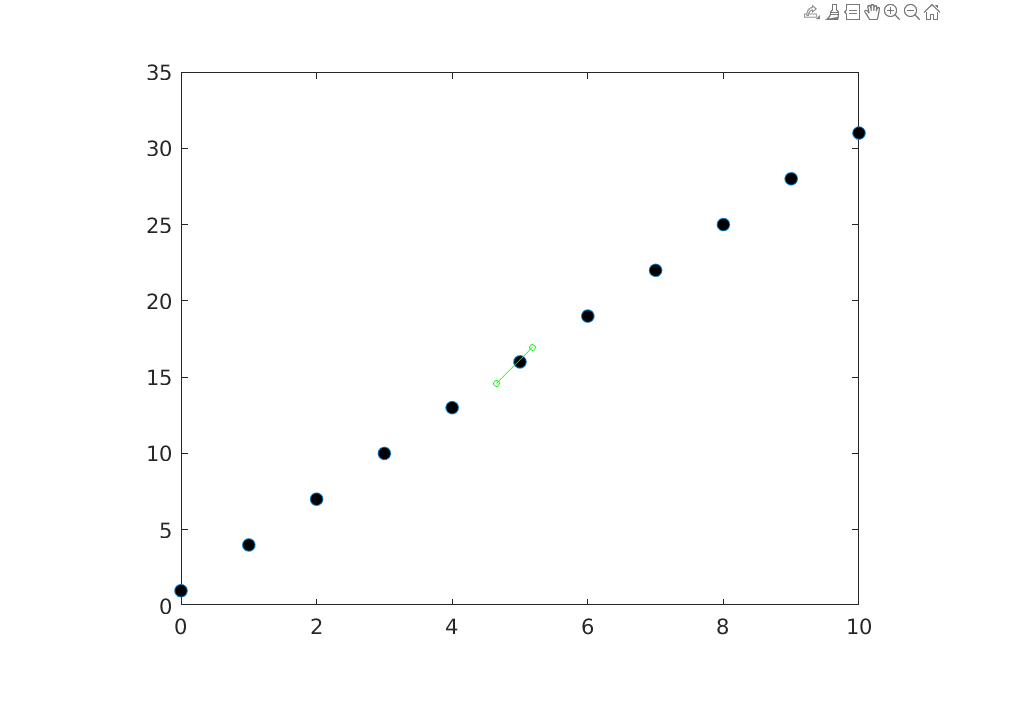


box = ceil(readPoints(img_name, 2)); box = box';

box_x = sort(box(:,1))'

box_x =    430   466


box_y = sort(box(:,2))'

box_y =    325   361


% make sure box has odd number of rows and columns for centering 
shape_orig = img(box_y(1):box_y(2), box_x(1):box_x(2),:)

shape_orig = 37×37 uint8 matrix
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   2

[shape_rows, shape_cols] = size(shape_orig)

shape_rows = 37

shape_cols = 37

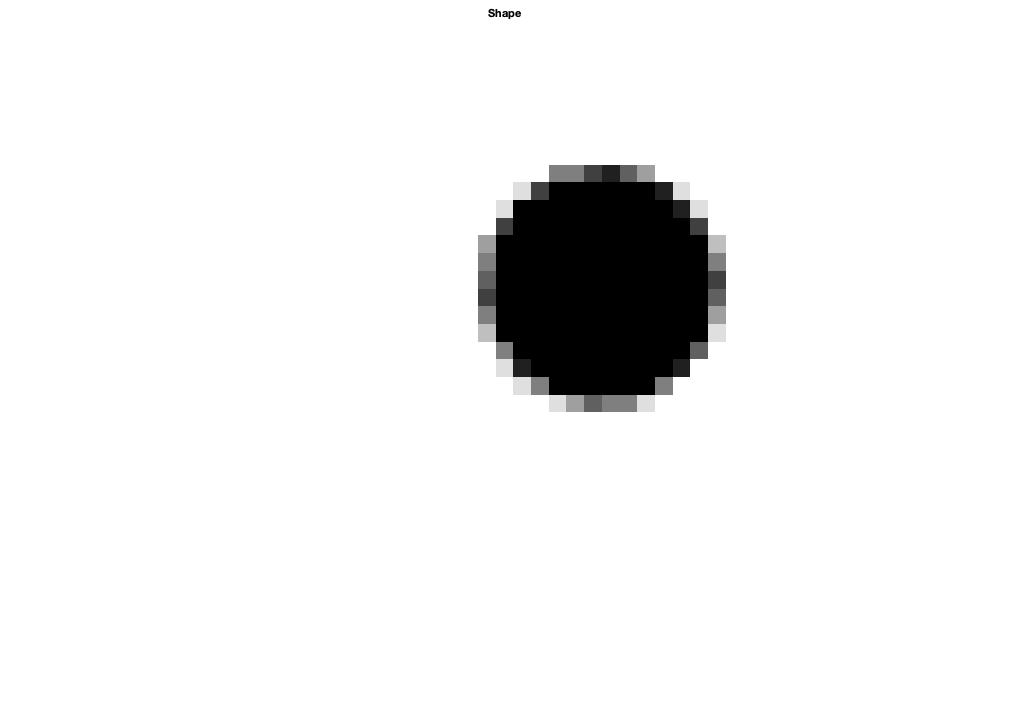


if mod(shape_rows, 2) == 0
    shape_orig = [shape_orig; 255*ones(1, shape_cols)]
    [shape_rows, shape_cols] = size(shape_orig)
end
if mod(shape_cols, 2) == 0
    shape_orig = [shape_orig 255*ones(shape_rows, 1)]
    [shape_rows, shape_cols] = size(shape_orig)
end

imshow(shape_orig,[])
title('Shape')

% add extra entries on outside of array to ensure it can be scanned by the image
img_ex = [255*ones(img_rows, shape_cols), img, 255*ones(img_rows, shape_cols)]

img_ex = 655×949 uint8 matrix
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255 

img_ex = [255*ones(shape_rows, img_cols+(2*shape_cols)); img_ex; 255*ones(shape_rows, img_cols+(2*shape_cols))]

img_ex = 729×949 uint8 matrix
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255 

% Filter image and map to ones and zeros
filter = 200

filter = 200


shape = shape_orig;
img_norm = img_ex;

img_norm(img_norm<=filter) = 1; img_norm(img_norm>filter) = 0

img_norm = 729×949 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

shape(shape<=filter) = 1; shape(shape>filter) = 0

shape = 37×37 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

shape = logical(shape)

shape = 37×37 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

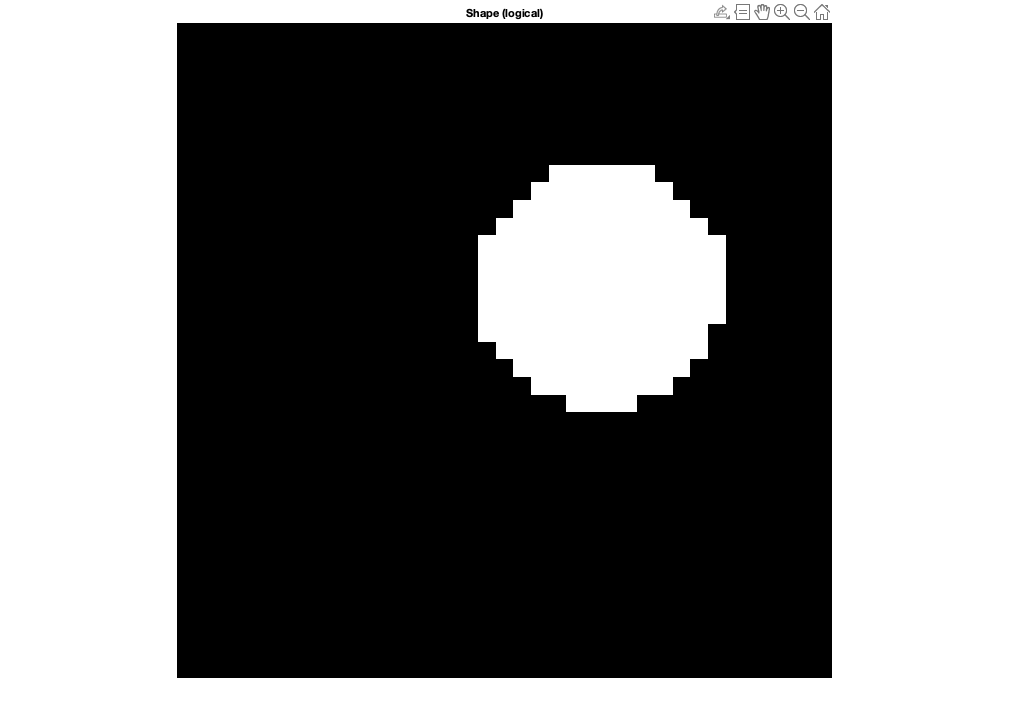


imshow(shape,[])
title('Shape (logical)')

% get shape center
shape_label=logical(shape);
props = regionprops(shape_label, shape, 'WeightedCentroid');
shape_center = round([props.WeightedCentroid])

shape_center =     24    15


% scan shape across coordinate area and save matches
matches = zeros(img_rows, img_cols);
x = 1;
y = 1;

% vertical loop over coordinate area
for j = shape_rows-shape_center(2):shape_rows-shape_center(2)+img_rows-1
    % horizontal loop over coordinate area
    for i = shape_cols-shape_center(1):shape_cols-shape_center(1)+img_cols-1
        % select shape sized section of coordinate area
        img_section = img_norm(j:j+shape_rows-1, i:i+shape_cols-1);
        % logical and values together to find possible matches
        matches(y,x) = sum(img_section & shape, 'all');
        x = x+1;
    end
    x = 1;
    y = y+1;
end

matches

matches =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

% filter matches
max_val = max(matches, [], 'all')

max_val = 153

matches_filter = 0.5

matches_filter = 0.5000


matches_sliced = matches;
matches_sliced(matches_sliced<=(matches_filter*max_val)) = 0

matches_sliced =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

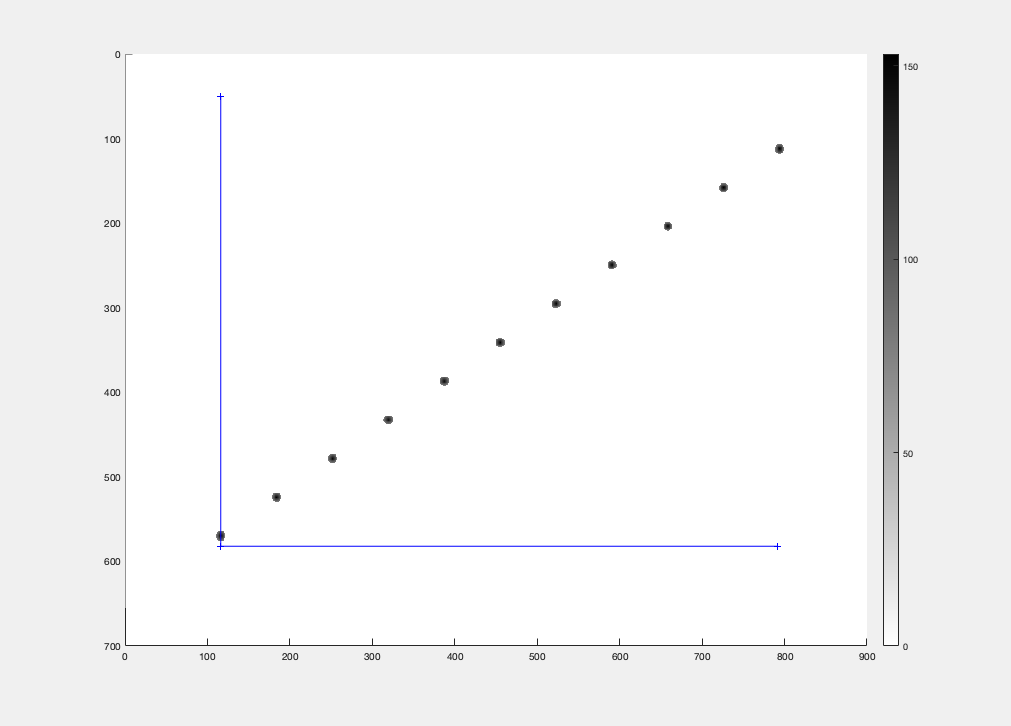

% plot matches
figure(1)
axis ij;
colormap('gray');
colormap(interp1([0;1],[1 1 1; 0 0 0],linspace(0,1,256)));
hold on;
imagesc(matches_sliced);
colorbar;
plot(x_axis_img(:,1), x_axis_img(:,2), 'b+-');
plot(y_axis_img(:,1), y_axis_img(:,2), 'b+-');
hold off;

clf('reset');

% Smooth matches
smoothing = true

smoothing = logical
   1



if smoothing
    % Smooth matches with area with 3x3 matrix
    w = 3;
    Nextra  = 0.5*(w-1);
    matches_p = interp2(1:img_cols,1:img_rows,matches_sliced,-Nextra+1:img_cols+Nextra,(-Nextra+1:img_rows+Nextra).','makima');    % 2D extrapolation must use 'spline' or 'makima' interpolation
    % Smooth data with sliding window
    H  = ones(w)./w^2; % The 2D averaging filter
    matches_smooth  = filter2(H,matches_p,'valid'); % The smooth resulting matrix
    
    % Smooth matches with area with 2x2 matrix
    w = 2;
    Nextra  = 0.5*(w-1);
    matches_p = interp2(1:img_cols,1:img_rows,matches_smooth,-Nextra+1:img_cols+Nextra,(-Nextra+1:img_rows+Nextra).','makima');    % 2D extrapolation must use 'spline' or 'makima' interpolation
    % Smooth data with sliding window
    H  = ones(w)./w^2; % The 2D averaging filter
    matches_smooth  = filter2(H,matches_p,'valid'); % The smooth resulting matrix
else
    matches_smooth = matches_sliced
end

% find regional maximums in image
regmax = imregionalmax(matches_smooth')

regmax = 875×655 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

sparse_regmax = sparse(regmax);
[x, y, ~] = find(sparse_regmax);
points_img = [x, y]

points_img =    794   112
   726   158
   658   204
   591   249
   523   295
   455   341
   387   387
   319   433
   252   478
   184   524



points_img_inrange = points_img;
points_img_inrange(find( (points_img(:,1) < x_axis_img(1,1)) | (points_img(:,1) > x_axis_img(2,1)) | (points_img(:,2) > y_axis_img(1,2)) | (points_img(:,2) < y_axis_img(2,2)) ), :) = []

points_img_inrange =    726   158
   658   204
   591   249
   523   295
   455   341
   387   387
   319   433
   252   478
   184   524
   116   570


% map values to coordinate area and axes scale
x = arrayfun(@(temp) interp1(x_axis_img(:,1), x_axis', temp),  x);
y = arrayfun(@(temp) interp1(y_axis_img(:,2), y_axis', temp),  y);

points_coord_with_nan = [x y]

points_coord_with_nan =        NaN   30.9211
    9.0237   27.8947
    8.0178   24.8684
    7.0266   21.9079
    6.0207   18.8816
    5.0148   15.8553
    4.0089   12.8289
    3.0030    9.8026
    2.0118    6.8421
    1.0059    3.8158


% remove NaN values
points_coord = points_coord_with_nan;
points_coord(any(isnan(points_coord), 2), :) = []

points_coord =     9.0237   27.8947
    8.0178   24.8684
    7.0266   21.9079
    6.0207   18.8816
    5.0148   15.8553
    4.0089   12.8289
    3.0030    9.8026
    2.0118    6.8421
    1.0059    3.8158
         0    0.7895


num_points = size(points_coord, 1)

num_points = 10

% sort points
sorted = true

sorted = logical
   1


if sorted
    points_img = sortrows(points_img,1)
    points_img_inrange = sortrows(points_img_inrange,1)
    points_coord_with_nan = sortrows(points_coord_with_nan,1)
    points_coord = sortrows(points_coord,1)
    lineformat = 'r*-'
else
    lineformat = 'r.'
end

points_img =    116   570
   184   524
   252   478
   319   433
   387   387
   455   341
   523   295
   591   249
   658   204
   726   158


points_img_inrange =    116   570
   184   524
   252   478
   319   433
   387   387
   455   341
   523   295
   591   249
   658   204
   726   158


points_coord_with_nan =          0    0.7895
    1.0059    3.8158
    2.0118    6.8421
    3.0030    9.8026
    4.0089   12.8289
    5.0148   15.8553
    6.0207   18.8816
    7.0266   21.9079
    8.0178   24.8684
    9.0237   27.8947


points_coord =          0    0.7895
    1.0059    3.8158
    2.0118    6.8421
    3.0030    9.8026
    4.0089   12.8289
    5.0148   15.8553
    6.0207   18.8816
    7.0266   21.9079
    8.0178   24.8684
    9.0237   27.8947


lineformat = 'r*-'

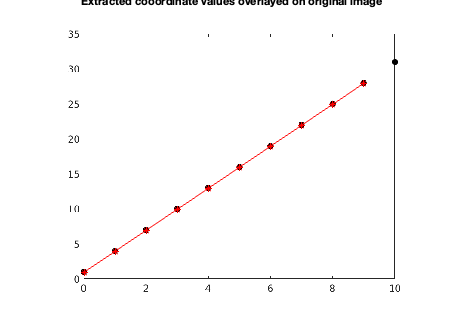

% plot of points overlayed
figure(2)
axis ij;
imshow(img_ex(shape_rows:img_rows+shape_rows, shape_cols:img_cols+shape_cols), []);
title('Extracted cooordinate values overlayed on original image')
hold on;
plot(points_img_inrange(:,1), points_img_inrange(:,2), lineformat);

clf('reset') ;

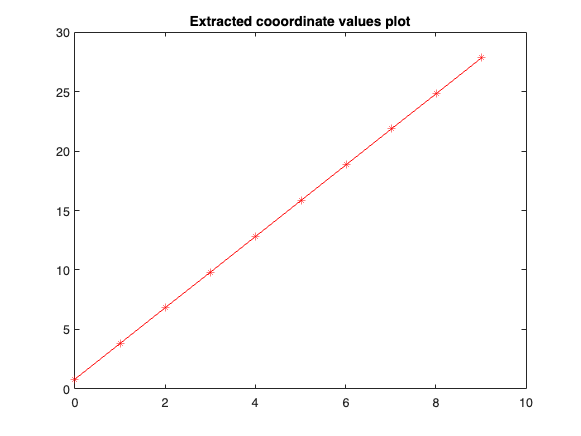

% plot of points
figure(3)
axis xy;
xlim(x_axis);
ylim(y_axis);
plot(points_coord(:,1), points_coord(:,2), lineformat);
title('Extracted cooordinate values plot')

clf('reset');

% get integer points and remove duplicates
points_coord_int = floor(points_coord)

points_coord_int =      0     0
     1     3
     2     6
     3     9
     4    12
     5    15
     6    18
     7    21
     8    24
     9    27


points_coord_int_unique = unique(points_coord_int,'rows')

points_coord_int_unique =      0     0
     1     3
     2     6
     3     9
     4    12
     5    15
     6    18
     7    21
     8    24
     9    27


num_unique_int_points = size(points_coord_int_unique, 1)

num_unique_int_points = 10

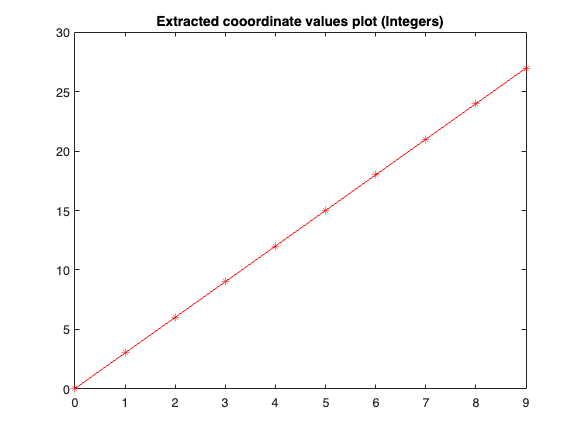

% plot of integer points
figure(4)
axis xy;
xlim(x_axis);
ylim(y_axis);
plot(points_coord_int_unique(:,1), points_coord_int_unique(:,2), lineformat);
title('Extracted cooordinate values plot (Integers)')

clf('reset');

function pts = readPoints(image, n)
    %readPoints   Read manually-defined points from image
    %   POINTS = READPOINTS(IMAGE) displays the image in the current figure,
    %   then records the position of each click of button 1 of the mouse in the
    %   figure, and stops when another button is clicked. The track of points
    %   is drawn as it goes along. The result is a 2 x NPOINTS matrix; each
    %   column is [X; Y] for one point.
    %
    %   POINTS = READPOINTS(IMAGE, N) reads up to N points only.
    if nargin < 2
        n = Inf;
        pts = zeros(2, 0);
    else
        pts = zeros(2, n);
    end
    imshow(image);     % display image
    xold = 0;
    yold = 0;
    k = 0;
    hold on;           % and keep it there while we plot
    while 1
        [xi, yi, but] = ginput(1);      % get a point
        if ~isequal(but, 1)             % stop if not button 1
            break
        end
        k = k + 1;
        pts(1,k) = xi;
        pts(2,k) = yi;
        if xold
            plot([xold xi], [yold yi], 'go-');  % draw as we go
        else
            plot(xi, yi, 'go');         % first point on its own
        end
        if isequal(k, n)
            break
        end
        xold = xi;
        yold = yi;
    end
    hold off;
    if k < size(pts,2)
        pts = pts(:, 1:k);
    end
end